% THIS SCRIPT CALCULATES AND PLOTS THE EGR STRESS AND STRAIN FOR MULTIPLE DIFFERENT MATERIALS AND PLOTS THEM
% HERE'S SOME MATLAB TIPS TO HELP:
% Firstly, be sure to paste this code into a New Live Script, way easier to
% work here than directly in the Command Window
% Semicolons keeps variables from being outputted when they're created,
% makes it easy to keep your outputs clean and check variables when needed
% Select multiple lines and use CTRL+R to make them all comments!
% ATTRIBUTION: ChatGPT, Mathworks.com

% Open .csv files and retrieve data
brass = '/Users/vinay/Downloads/Brass_1_1.csv';
brass_data = readtable(brass,'HeaderLines',5);

al2024 = '/Users/vinay/Downloads/Al2024_1_1.csv';
al2024_data = readtable(al2024,'HeaderLines',5);

steel = '/Users/vinay/Downloads/Steel_1_1.csv';
steel_data = readtable(steel,'HeaderLines',5);

% To maintain consistent naming conventions, I changed the name of the file
% I downloaded from D2L. Originally "Al6061_1.csv", now "Al6061_1_1.csv"
al6061 = '/Users/vinay/Downloads/Al6061_1_1.csv';
al6061_data = readtable(al6061,'HeaderLines',5);

% Define material properties
brass_width = 15.19;
brass_thickness = 3.18;
brass_length = 70.69;

al2024_width = 13.97;
al2024_thickness = 1.63;
al2024_length = 71.12;

steel_width = 15.09;
steel_thickness = 0.61;
steel_length = 69.29;

al6061_width = 12.9;
al6061_thickness = 1.57;
al6061_length = 69.65;

% Extract data from tables, be careful here to use correct indices
brass_time = brass_data{3:1325, 2};
brass_displacement = brass_data{3:1325, 3};
brass_force = brass_data{3:1325, 4};

al2024_time = al2024_data{3:757, 2};
al2024_displacement = al2024_data{3:757, 3};
al2024_force = al2024_data{3:757, 4};

steel_time = steel_data{3:1220, 2};
steel_displacement = steel_data{3:1220, 3};
steel_force = steel_data{3:1220, 4};

al6061_time = al6061_data{3:620, 2};
al6061_displacement = al6061_data{3:620, 3};
al6061_force = al6061_data{3:620, 4};

% Calculate engineering stress and strain values for each material,
% tabularize and display in output
brass_egrstress = brass_force ./ (brass_width * brass_thickness);
brass_egrstrain = brass_displacement ./ brass_length;
brass_table = table(brass_time,brass_egrstrain,brass_egrstress);
disp(brass_table);

    brass_time    brass_egrstrain    brass_egrstress
    __________    _______________    _______________

           0                 0           32.945     
         0.1        5.2341e-05           34.541     
       0.187        0.00018249            39.73     
        0.22        0.00032112           45.044     
        0.25        0.00046683           50.355     
        0.29        0.00062809           55.596     
       0.389        0.00090678           60.778     
       0.466         0.0011402           65.956     
       0.545         0.0013892           71.137     
       0.635          0.001648           76.339     
       0.718         0.0018984           81.572     
       0.806          0.002163           86.792     
       0.898         0.0024261           91.994     
       0.978         0.0026835           97.187     
       1.075         0.0029679           102.41  


al2024_egrstress = al2024_force ./ (al2024_width * al2024_thickness); 
al2024_egrstrain = al2024_displacement ./ al2024_length; 
al2024_table = table(al2024_time,al2024_egrstrain,al2024_egrstress);
disp(al2024_table);

    al2024_time    al2024_egrstrain    al2024_egrstress
    ___________    ________________    ________________

          0                    0            22.043     
        0.1           7.5928e-05             23.77     
        0.2           0.00026294            29.551     
        0.3           0.00068476             38.92     
        0.4           0.00096879            44.984     
        0.5            0.0012669             50.84     
        0.6            0.0015636            56.416     
        0.7            0.0018729             62.04     
        0.8            0.0021569            67.139     
        0.9             0.002462            72.669     
          1            0.0027489             77.76     
        1.1             0.003054            83.264     
        1.2            0.0033549            88.527     
        1.3            0.0036474            93.749     
 


steel_egrstress = steel_force ./ (steel_width * steel_thickness); 
steel_egrstrain = steel_displacement ./ steel_length; 
steel_table = table(steel_time,steel_egrstrain,steel_egrstress);
disp(steel_table);

    steel_time    steel_egrstrain    steel_egrstress
    __________    _______________    _______________

           0                 0           26.194     
         0.1        7.3604e-05           31.368     
         0.2        0.00027421           47.233     
       0.293        0.00068697           74.406     
       0.393        0.00096839           87.745     
       0.493          0.001283           102.59     
       0.593         0.0015846           115.54     
       0.693         0.0018877           128.51     
       0.793         0.0022023           141.38     
       0.893         0.0024924           152.74     
       0.993         0.0028085           165.16     
       1.093         0.0031029            176.2     
       1.193         0.0034204            188.5     
       1.293         0.0037235           199.27     
       1.393         0.0040266              210  


al6061_egrstress = al6061_force ./ (al6061_width * al6061_thickness); 
al6061_egrstrain = al6061_displacement ./ al6061_length;
al6061_table = table(al6061_time,al6061_egrstrain,al6061_egrstress);
disp(al6061_table);

    al6061_time    al6061_egrstrain    al6061_egrstress
    ___________    ________________    ________________

         NaN                 NaN               NaN     
         NaN                 NaN               NaN     
           0                   0            21.284     
         0.1          5.1687e-05            22.702     
         0.2          0.00022972            29.123     
       0.275          0.00058722             41.59     
       0.375          0.00088299            51.409     
       0.475           0.0011831            60.053     
       0.575           0.0014932            67.233     
       0.675           0.0018019             74.62     
       0.775           0.0020991            81.747     
       0.875           0.0024078            89.082     
       0.975           0.0026992            95.758     
       1.075           0.0030165            102.91     
 

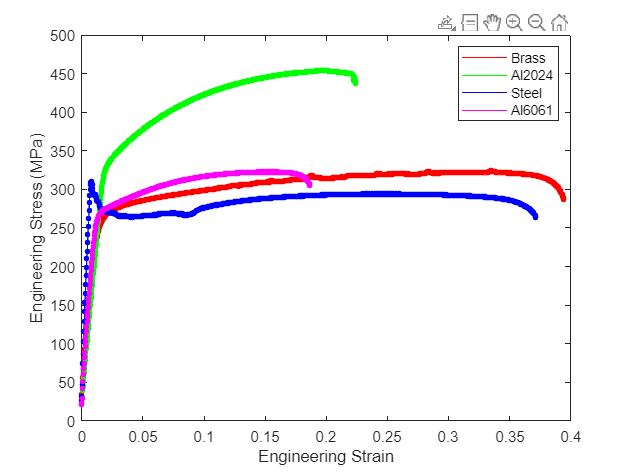


% Plot the data for each material, scatter plot and line
brass_plot = plot(brass_egrstrain, brass_egrstress, 'Color', 'red');
hold on
al2024_plot = plot(al2024_egrstrain, al2024_egrstress, 'Color', 'green');
steel_plot = plot(steel_egrstrain, steel_egrstress, 'Color', 'blue');
al6061_plot = plot(al6061_egrstrain, al6061_egrstress, 'Color', 'magenta');

scatter(brass_egrstrain, brass_egrstress, 10, 'filled', 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'red');
scatter(al2024_egrstrain, al2024_egrstress, 10, 'filled', 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'green');
scatter(steel_egrstrain, steel_egrstress, 10, 'filled', 'MarkerFaceColor', 'blue', 'MarkerEdgeColor', 'blue');
scatter(al6061_egrstrain, al6061_egrstress, 10, 'filled', 'MarkerFaceColor', 'magenta', 'MarkerEdgeColor', 'magenta');

xlabel('Engineering Strain');
ylabel('Engineering Stress (MPa)'); 
legend('Brass','Al2024','Steel','Al6061');